# **Assignment:  Feature Classification  of CWRU Dataset**

**Name: Jin Kwak/21900031  **

**Date: 24.09.24**

## **Introduction**

1. **Read the paper and understand the whole process**

This Assignment is implementation a part of classification in the literature 

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**2. Apply KNN and SVM  classification methods with all  features **

**3. Apply KNN and SVM  classification methods with Selected features by Forward/Backward eliminiation**

- Read here: [https://kr.mathworks.com/help/stats/sequentialfs.html](https://kr.mathworks.com/help/stats/sequentialfs.html)

**4. Apply KNN and SVM  classification with Reduce feature dimension by PCA or LDA**

- Read here:  https://kr.mathworks.com/help/stats/pca.html?lang=en

Which gives the best evaluation performance on Test set? Also try to optimize KNN and SVM

**This LAB is about classification of ball bearing fault using feature selection, SVM, KNN, and reduced feature dimension by PCA**

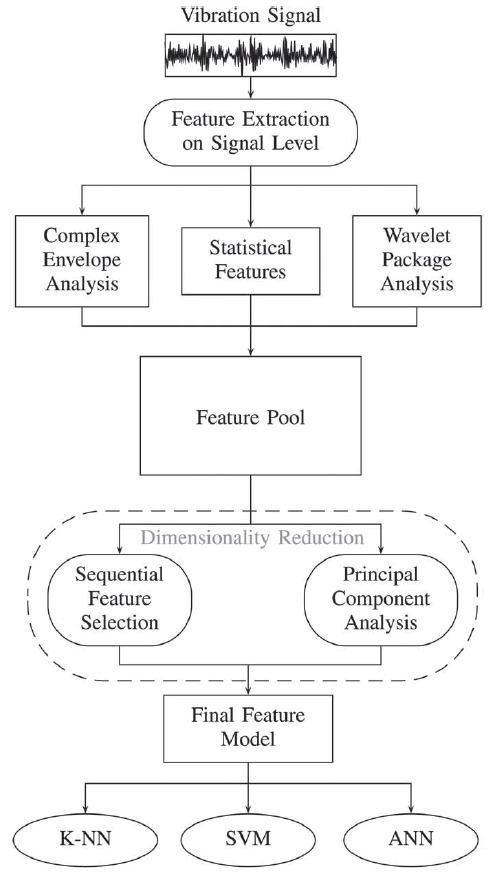

## Dataset

**Given: Feature Extracted from CWRU bearing dataset **

Classes:

-  Normal / Outer Race fault / Inner Race fault / Ball fault

The given data is divided by Train set and Test set 

**Note**

Training. K-fold, cross-validation is performed on Train Dataset only.

Test dataset is used for Evaluation.

## Load Dataset

close all
clear
addpath('../../Dataset/CWRU_selected_Dataset/Feature_data/')
% Train set
load("sample_train.mat");

% Test set
load("sample_test.mat");

## **Section 1: Classification with all features**

You need to explain the process clearly and analyze the results

According to the paper(Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis), 

**KNN **classifies the category of simple non-parametrics.

**SVM **is one of the powerful methods in machine learning

Therefore, the two classification methods are introduced in this part.

**Classfier 1: SVM**

For multi-class SVM, use      **fitcecoc( )**

**fitcecoc - 서포트 벡터 머신 또는 다른 분류기에 대해 다중클래스 모델 피팅하기**

**    테이블 Tbl에 포함된 예측 변수와 Tbl.ResponseVarName에 포함된 클래스 레이블을 사용**

**    하여 전체 훈련된 다중클래스 오류 수정 출력 코드(ECOC) 모델을 반환합니다.**

[https://kr.mathworks.com/help/stats/fitcecoc.html?lang=en](https://kr.mathworks.com/help/stats/fitcecoc.html?lang=en)

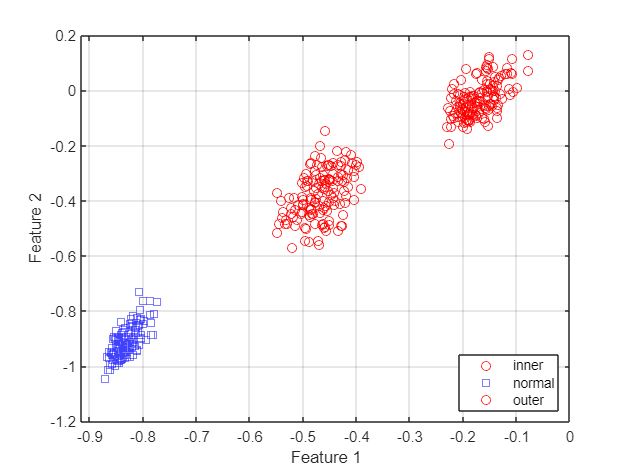

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SVM %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

feature1_SVM = "kv"; 
feature2_SVM = "mf";
feature3_SVM = 'cf';
% x_train_svm(:,1) = table2array(glob_all_train(:,1:11, 13:42));
x_train_svm(:,1) = table2array(glob_all_train(:,feature1_SVM));
x_train_svm(:,2) = table2array(glob_all_train(:,feature2_SVM));
x_train_svm(:,3) = table2array(glob_all_train(:,feature3_SVM));
class_SVM    = class_cwru_train;

x_test_svm(:,1) = table2array(glob_all_test(:,feature1_SVM));
x_test_svm(:,2) = table2array(glob_all_test(:,feature2_SVM));
x_test_svm(:,3) = table2array(glob_all_test(:,feature3_SVM));
X = x_train_svm;
X_test = x_test_svm;
Y = class_SVM;
N = size(X,1);
Y = categorical(Y);
Y_test = class_cwru_test;

feature_idx = [1:11];
feature_idx = [4,9,14,17,20,22,26,27,32,35,41];
% feature_idx = [1:11,13:42];
x_train = table2array(glob_all_train(:, feature_idx));
cwru_train = table2array(glob_all_train(:, feature_idx));
cwru_test  = table2array(glob_all_test(:, feature_idx));
% Random Plot
figure;
gscatter(X(:,1),X(:,2),Y,'rb','os'); hold on; grid on;
xlabel('Feature 1');
ylabel('Feature 2');

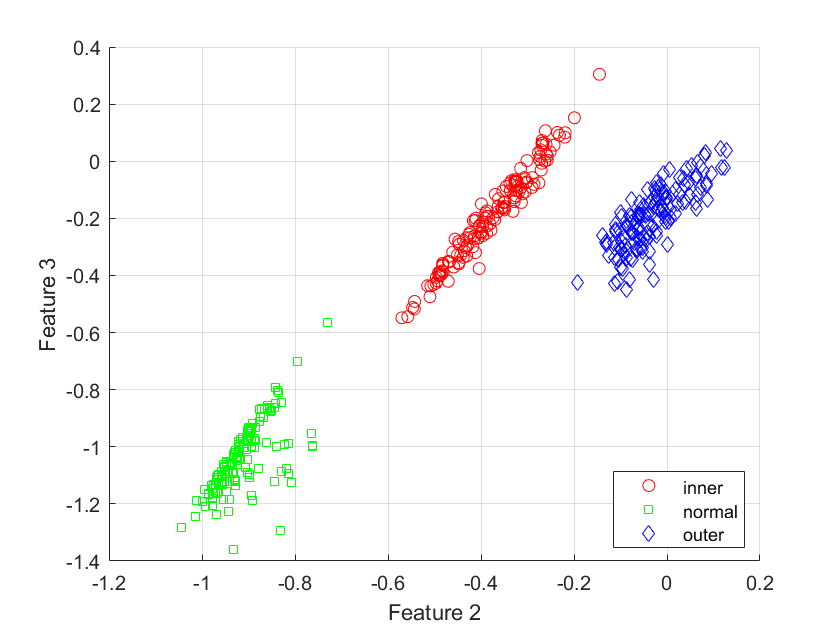

figure; hold on; grid on;
gscatter(X(:,2), X(:,3), Y,'rgb','osd');
xlabel('Feature 2');
ylabel('Feature 3');

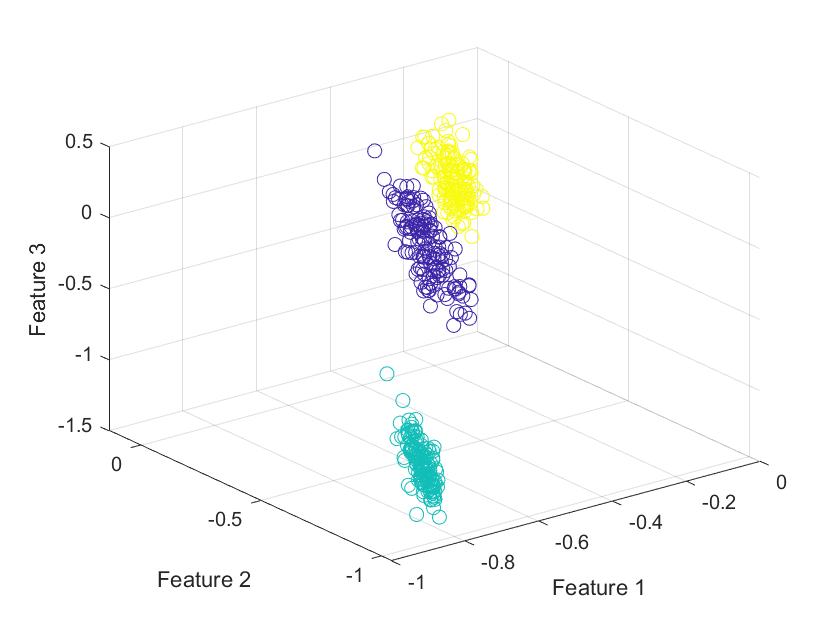


figure;
scatter3(X(:,1), X(:,2), X(:,3), 50, Y);
xlabel('Feature 1');
ylabel('Feature 2');
zlabel('Feature 3');
grid on;

k = 10;

cv = cvpartition(class_SVM,'KFold',k);
% Train
SVM = fitcecoc(x_train, Y, 'Learners', 'svm','FitPosterior',true, ...
 'ClassNames', {'outer', 'inner', 'normal'}, ...
 'Verbose',2);

144개의 음성 관측값과 144개의 양성 관측값을 사용하여 전체 3개 중에서 이진 학습기 1(SVM)을(를) 훈련시키는 중입니다.
음성 클래스 인덱스: 2
양성 클래스 인덱스: 1

학습기 1(SVM)에 대해 사후 확률을 피팅하는 중입니다.
144개의 음성 관측값과 144개의 양성 관측값을 사용하여 전체 3개 중에서 이진 학습기 2(SVM)을(를) 훈련시키는 중입니다.
음성 클래스 인덱스: 3
양성 클래스 인덱스: 1

학습기 2(SVM)에 대해 사후 확률을 피팅하는 중입니다.
144개의 음성 관측값과 144개의 양성 관측값을 사용하여 전체 3개 중에서 이진 학습기 3(SVM)을(를) 훈련시키는 중입니다.
음성 클래스 인덱스: 3
양성 클래스 인덱스: 2

학습기 3(SVM)에 대해 사후 확률을 피팅하는 중입니다.


%%% Analyze
% Resubstitution error
resubLoss(SVM)

ans = 0.0741

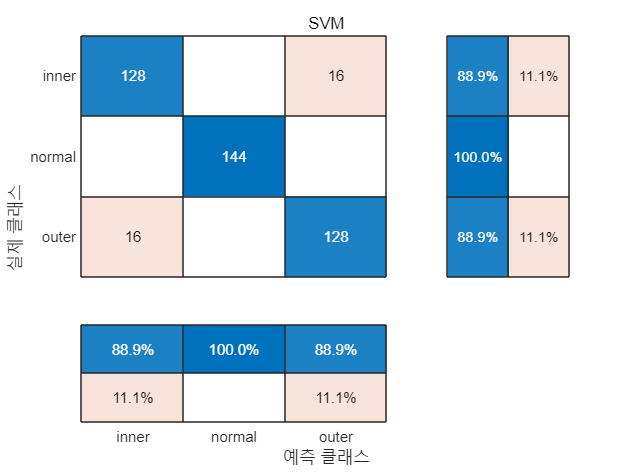

% Confusion Matrix
mlClass = resubPredict(SVM);
mlClass = categorical(mlClass);
figure;
confusionchart(Y,mlClass, ...
    'Title','SVM', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

This Confusion Matrix shows classification performance with resubstitution prediction

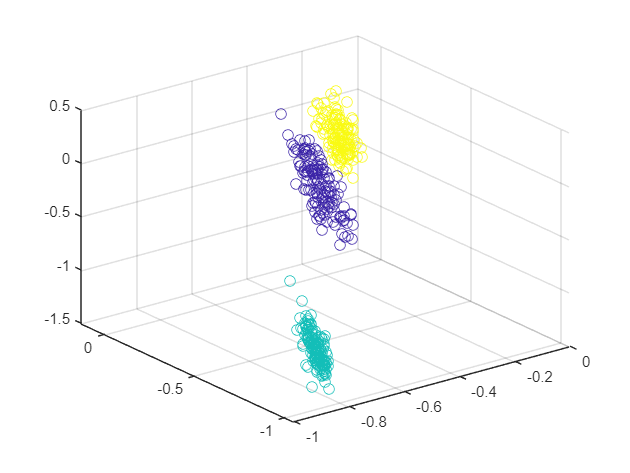

% Predict Scores over the grid
d = 0.02;
% [x1Grid,x2Grid,x3Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
%                                   min(X(:,2)):d:max(X(:,2)), ...
%                                   min(X(:,3)):d:max(X(:,3)));
% xGrid = [x1Grid(:),x2Grid(:),x3Grid(:)];
% [~,scores] = predict(SVM,xGrid);

% Plot Figures
figure;
scatter3(X(:,1), X(:,2), X(:,3), 50, Y);

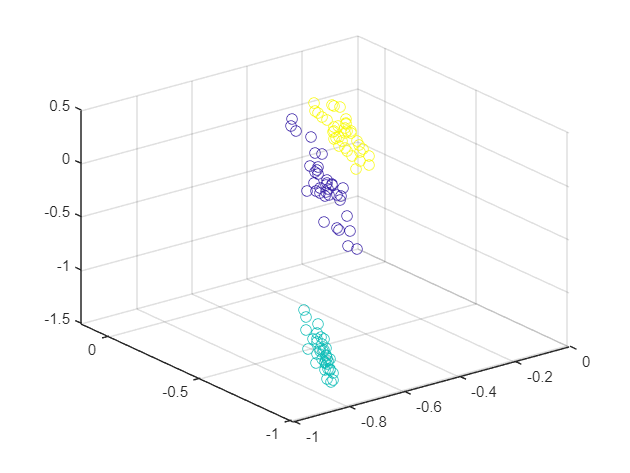


% [x1Grid,x2Grid,x3Grid] = meshgrid(min(X_test(:,1)):d:max(X_test(:,1)),...
%                                   min(X_test(:,2)):d:max(X_test(:,2)), ...
%                                   min(X_test(:,3)):d:max(X_test(:,3)));
% xGrid = [x1Grid(:),x2Grid(:),x3Grid(:)];
% [~,scores] = predict(SVM,xGrid)
Y_test= categorical(Y_test);
% Plot Figures
figure;
scatter3(X_test(:,1), X_test(:,2), X_test(:,3), 50, Y_test );

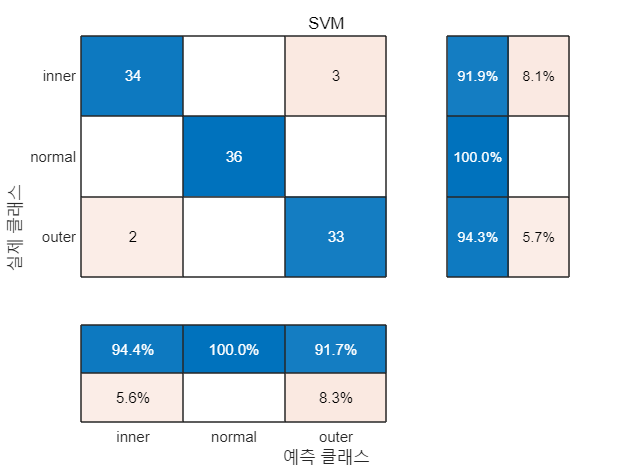

class_original= predict(SVM, cwru_test);
figure;
confusionchart(class_original,class_cwru_test, ...
    'Title','SVM', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

**Classifier 2: KNN**

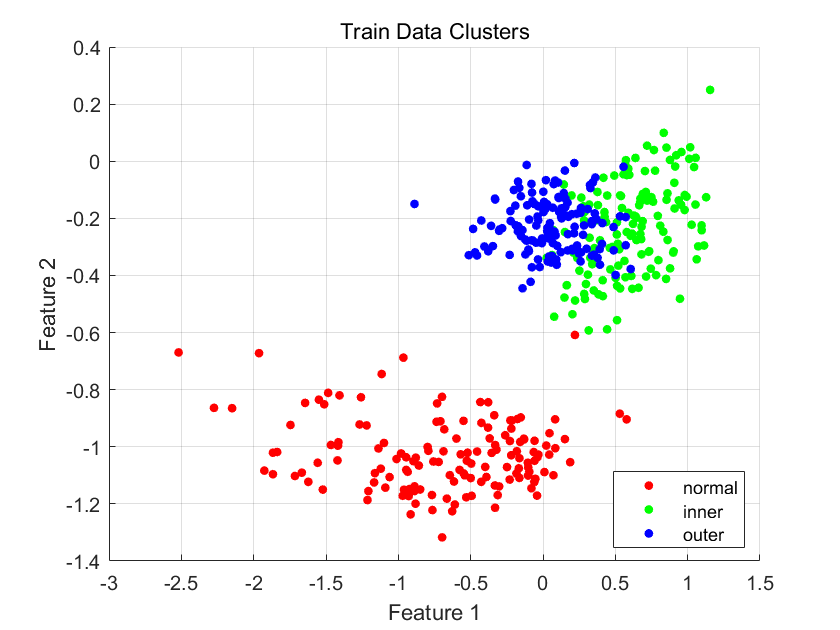

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% KNN %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
rng(1)
% feature1_SVM = "kv"; 
% feature2_SVM = "mf";
% feature3_SVM = 'cf';
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
feature3 = feature3_SVM;
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
X(:, 3) = table2array(glob_all_train(:, feature3));
X = table2array(glob_all_train(:, feature_idx));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl_train_KNN=table(X(:, 1),X(:, 2),X(:,3),Y);


X_test_KNN(:, 1) = table2array(glob_all_test(:, feature1));
X_test_KNN(:, 2) = table2array(glob_all_test(:, feature2));
X_test_KNN(:, 3) = table2array(glob_all_test(:, feature3));
X_test_KNN = table2array(glob_all_test(:,feature_idx));
Y_test_KNN= class_cwru_test;                                 
Ntest=size(X_test_KNN,1);

% tbl_test_KNN=table(X_test_KNN(:, 1),X_test_KNN(:, 2),X_test_KNN(:, 3),Y_test_KNN);
tbl_test_KNN=table(X_test_KNN,Y_test_KNN);
figure; hold on; grid on;
gscatter(X(:,1),X(:,2),Y)
title('Train Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

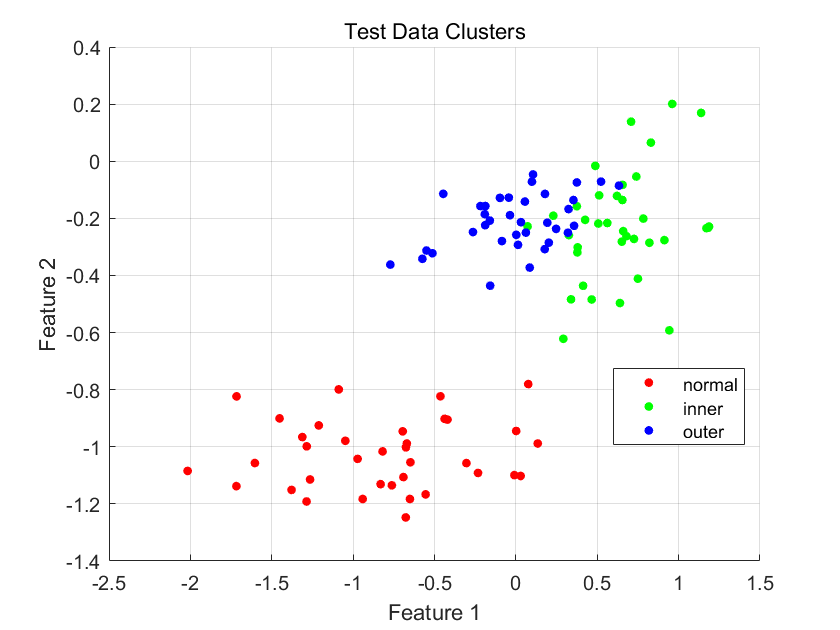

figure; hold on; grid on;
gscatter(X_test_KNN(:,1),X_test_KNN(:,2),Y_test_KNN)
title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

rng(10); 

Mdl = fitcknn(X, Y)

Mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'inner'  'normal'  'outer'}
           ScoreTransform: 'none'
          NumObservations: 432
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


loss_train = loss(Mdl, X, Y)

loss_train = 0

cv = cvpartition(Y,'KFold',10) 

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

cv_val = crossval(Mdl,'CVPartition',cv);
error  = kfoldLoss(cv_val)

error = 0.0579

% Predict test data
predictClass = predict(Mdl, X_test_KNN)

predictClass = 108×1 cell 배열
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


loss_test=loss(Mdl, X_test_KNN, Y_test_KNN)

loss_test = 0.0185

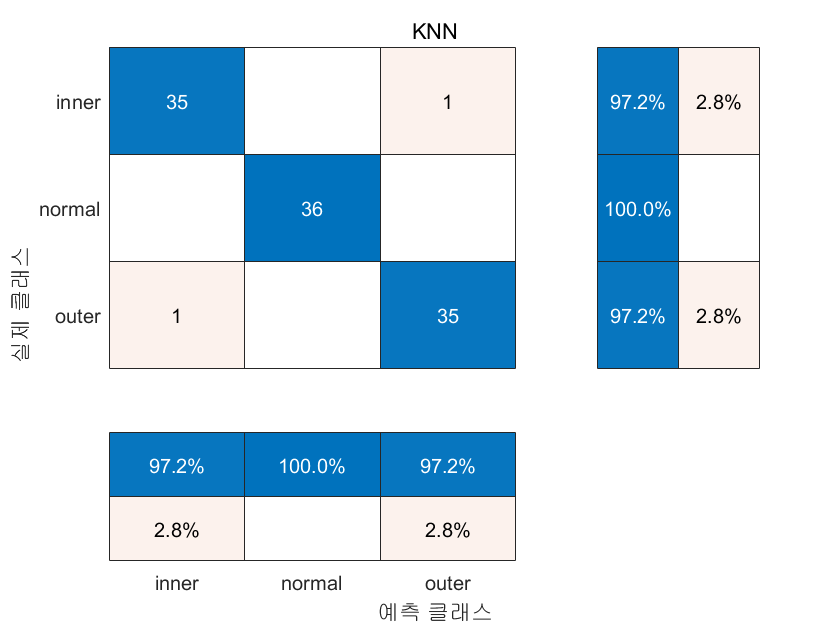

figure;
conf_mat = confusionchart(Y_test_KNN, predictClass, ...
    'Title','KNN', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

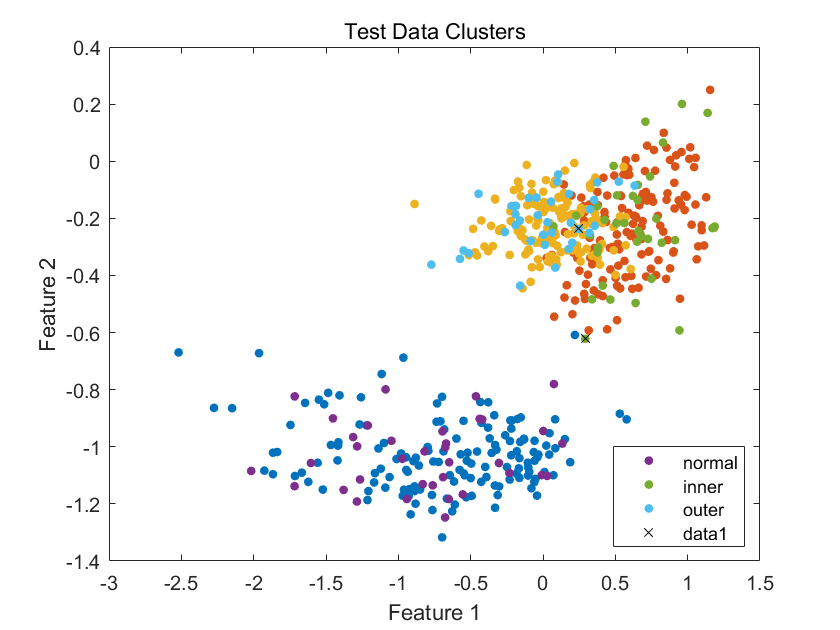

bad = ~strcmp(predictClass,Y_test_KNN);
color = lines(6);               % Generate color values
figure
gscatter(X(:,1),X(:,2),Y, color(1:3,:))
hold on
gscatter(X_test_KNN(:,1),X_test_KNN(:,2),Y_test_KNN, color(4:6,:))
hold on;
plot(X_test_KNN(bad,1), X_test_KNN(bad,2), 'kx');
hold off;
title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.046296 |     0.18779 |    0.046296 |    0.046296 |            3 |    minkowski |
|    2 | Accept |    0.053241 |      0.1001 |    0.046296 |    0.046611 |           18 |    cityblock |
|    3 | Accept |     0.31713 |    0.059837 |    0.046296 |    0.051941 |          141 |    euclidean |
|    4 | Accept |     0.06713 |    0.053818 |    0.046296 |    0.052256 |            2 |       cosine |
|    5 | Accept |    0.078704 |    0.045118 |    0.046296 |     0.04648 |            2 |    minkowski |
|    6 | Accept |     0.06713 |    0.027681 |    0.046296 |     

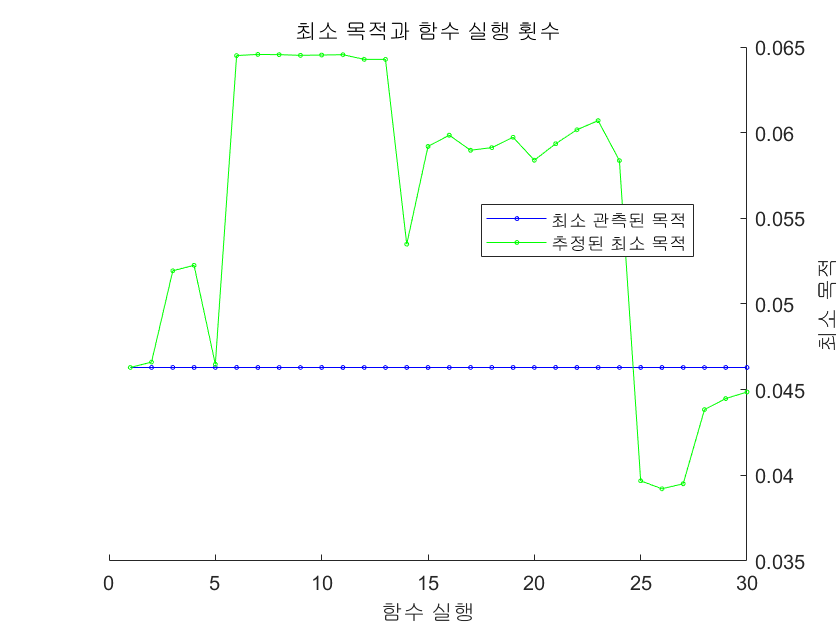

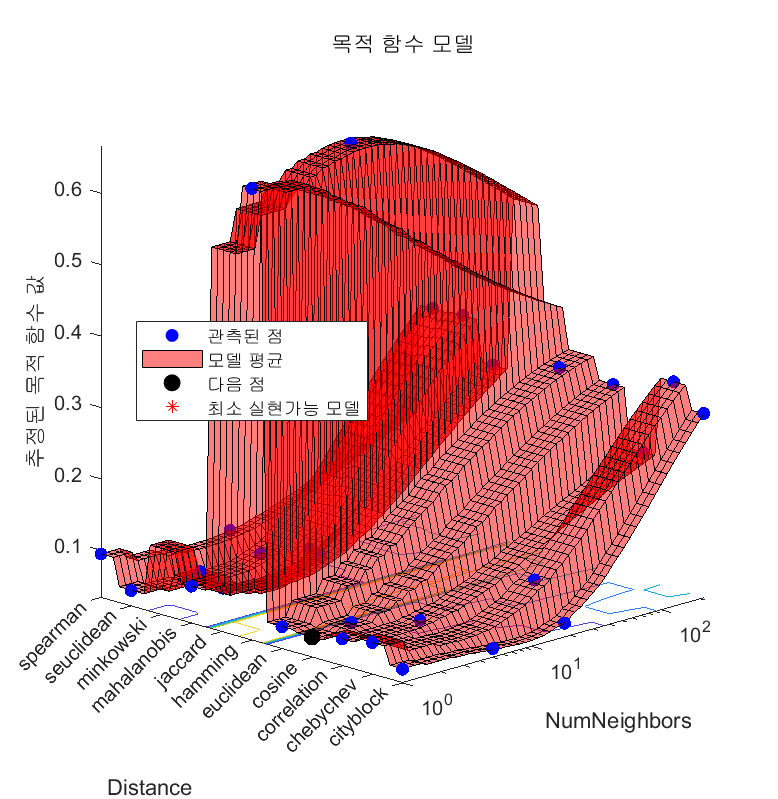


__________________________________________________________
최적화가 완료되었습니다.
MaxObjectiveEvaluations 30회에 도달했습니다.
총 함수 실행 횟수: 30
총 경과 시간: 18.1015초
총 목적 함수 실행 시간: 1.6676

최선의 관측된 실현가능점:
    NumNeighbors    Distance 
    ____________    _________

         3          minkowski

관측된 목적 함수 값 = 0.046296
추정된 목적 함수 값 = 0.050338
함수 실행 시간 = 0.18779

최선의 추정된 실현가능점(모델에 따라 다름):
    NumNeighbors    Distance 
    ____________    _________

         5          cityblock

추정된 목적 함수 값 = 0.044864
추정된 함수 실행 시간 = 0.049037



Mdl =   ClassificationKNN
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'inner'  'normal'  'outer'}
                       ScoreTransform: 'none'
                      NumObservations: 432
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'cityblock'
                         NumNeighbors: 5


  Properties, Methods


Mdl = fitcknn(X,Y,'OptimizeHyperparameters','auto',...
     'HyperparameterOptimizationOptions',...
     struct('AcquisitionFunctionName','expected-improvement-plus'))

## **Section 2: Classification on Selected features**

Wrapper Type Feature Selection: Sequential Feature Selection

Wrapper Type: Selection of features while training by adding(forward) or removing(backward) features

**Use  :  **`inmodel = sequentialfs(fun,X,y)`

%%% YOUR CODE GOES HERE
class_train = categorical(class_cwru_train)                ;
class_test  = categorical(class_cwru_test)                 ;

rng(0)
Y = height(cwru_train);         % Size of table
cv = cvpartition(Y,'KFold',10)  % k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

rng('default');
lossfun         = 'mincost';
opts            = statset('Display','iter');

fun   = @(XT,yT,Xt,yt)loss(fitcecoc(XT,yT),Xt,yt);    % MultiClass SVM
dir   = 'forward';    

[inmodel, history] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 9번 열 추가, 기준값 0.00479725
2단계, 1번 열 추가, 기준값 0.00223331
3단계, 5번 열 추가, 기준값 0.0021104
4단계, 4번 열 추가, 기준값 0.00175028
5단계, 8번 열 추가, 기준값 0.00174542
6단계, 6번 열 추가, 기준값 0.00171411
최종적으로 포함된 열: 1 4 5 6 8 9 


inmodel = 1×11 logical 배열
   1   0   0   1   1   1   0   1   1   0   0


history = 다음 필드를 포함한 struct :
      In: [6×11 logical]
    Crit: [0.0048 0.0022 0.0021 0.0018 0.0017 0.0017]


mdl = fitcecoc(cwru_train, class_train);
cvmdl = crossval(mdl) 

cvmdl =   ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'}
           ResponseName: 'Y'
        NumObservations: 432
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [inner    normal    outer]
         ScoreTransform: 'none'


  Properties, Methods


accuracy = 1 - kfoldLoss(cvmdl)

accuracy = 0.9213

idx_select = find(inmodel);     
cwru_train_select  = cwru_train(:, idx_select);
cwru_test_select  = cwru_test(:, idx_select);

mdl_select = fitcecoc(cwru_train_select, class_train);
cvmdl_select = crossval(mdl_select)

cvmdl_select =   ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'}
           ResponseName: 'Y'
        NumObservations: 432
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [inner    normal    outer]
         ScoreTransform: 'none'


  Properties, Methods


accuracy_select = 1 - kfoldLoss(cvmdl_select)

accuracy_select = 0.9190

error = loss(mdl, cwru_test, class_test);
accuracy = 1-error

accuracy = 0.9444

error_select = loss(mdl_select, cwru_test_select,class_test);
accuracy_select = 1-error_select

accuracy_select = 0.9352

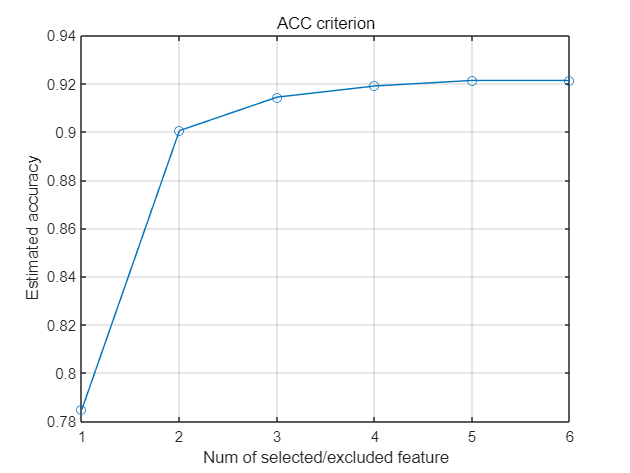

feat_num = length(history.In(:,1));
accuracy_hst = zeros(feat_num, 1);

for i=1:feat_num
    idx_hst = find(history.In(i, :));   
    mdl_hst = fitcecoc(cwru_train(:,idx_hst), class_train);
    cvmdl_hst = crossval(mdl_hst); 
    accuracy_hst(i) = 1 - kfoldLoss(cvmdl_hst);
end
figure;
plot(accuracy_hst, '-o'); title("ACC criterion");   grid on;
xlabel("Num of selected/excluded feature"); ylabel("Estimated accuracy");

dir = 'backward';
[inmodel_b, history_b] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir);

역방향 순차적 특징 선택 시작:
포함된 초기 열: all
포함해야 할 열: none
1단계, 초기 열 사용, 기준값 0.00170264
2단계, 3번 열 제거, 기준값 0.00162406
3단계, 4번 열 제거, 기준값 0.00150558
최종적으로 포함된 열: 1 2 5 6 7 8 9 10 11 


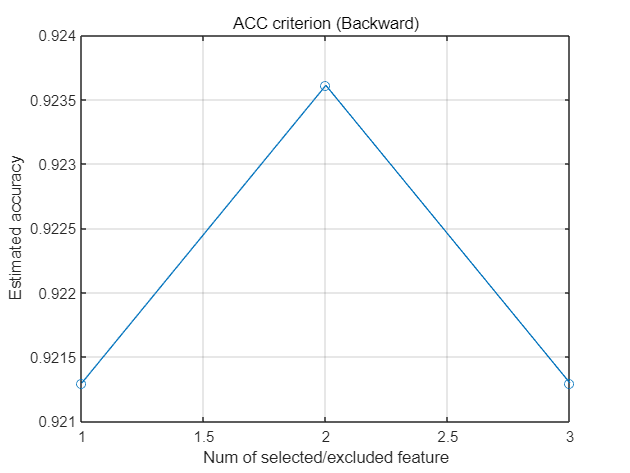


feat_num = length(history_b.In(:,1));
accuracy_hst = zeros(feat_num, 1);

for i=1:feat_num
    idx_hst = find(history_b.In(i, :));   
    mdl_hst = fitcecoc(cwru_train(:,idx_hst), class_train);
    cvmdl_hst = crossval(mdl_hst); 
    accuracy_hst_b(i) = 1 - kfoldLoss(cvmdl_hst);
end
figure;
back_num = feat_num:-1:1;
plot(back_num,accuracy_hst_b, '-o'); title("ACC criterion (Backward)");   grid on;
xlabel("Num of selected/excluded feature"); ylabel("Estimated accuracy");

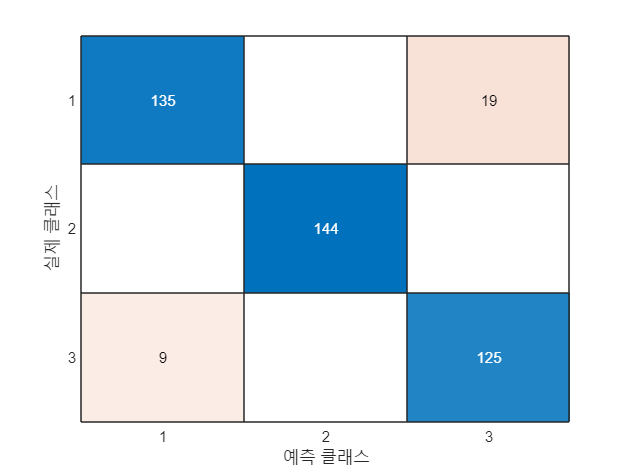


class_original= predict(mdl, cwru_train);
class_select  = predict(mdl_select, cwru_train(:, idx_select));

conf_mat_original = confusionmat(class_original, class_train);
conf_mat_select   = confusionmat(class_select  , class_train);
figure;
confusionchart(conf_mat_original);

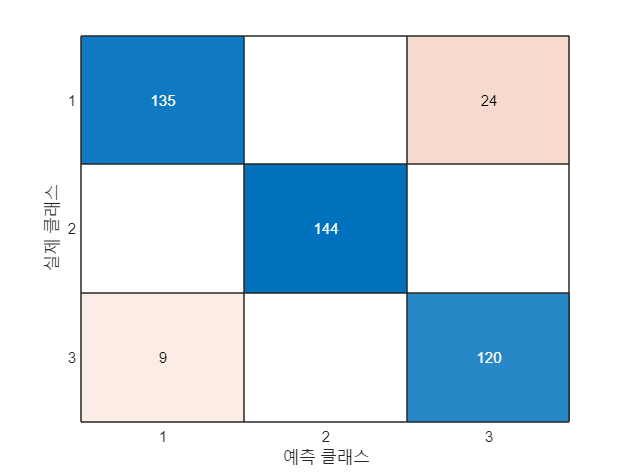

figure;
confusionchart(conf_mat_select);

## **Section 3: Classification on Reduced Features**

In this section, PCA is applied on CWRU dataset.

The coefficients(Eigenvectors of X covariance matrix), score(Converted X onto PCA basis), roots(Eigen values) of PCA is analyzed

**Use: **[`coeff = pca(X)`](https://kr.mathworks.com/help/stats/pca.html?lang=en#d123e644629)`, `[`coeff = pca(X,Name,Value)`](https://kr.mathworks.com/help/stats/pca.html?lang=en#d123e644661)

rng(0);
% coeff: Eigenvectors of X covariance matrix
% score: Converted X onto PCA basis 
% roots: Eigenvalues of X covariance matrix
[coeff,score,roots,~, explained, pcaCenter] = pca(cwru_train);

pcacov(cwru_train)

ans =     0.1715   -0.1523   -0.1328    0.3863    0.0406    0.7176    0.2230   -0.4149    0.1288   -0.1594   -0.0047
    0.1524   -0.2548    0.1644   -0.3142   -0.0392    0.3315   -0.3504    0.3813    0.6369    0.0234   -0.0153
   -0.3774    0.4580   -0.1971    0.5422    0.1318    0.0552   -0.0044    0.4521    0.2987   -0.0243   -0.0143
    0.3805    0.3186   -0.1069   -0.0195   -0.0637    0.0138    0.1600   -0.0749    0.1399    0.7356   -0.3818
    0.3069    0.5064   -0.0144   -0.2246   -0.1371    0.1417   -0.1011    0.0879   -0.1581   -0.5682   -0.4405
    0.3951   -0.0938   -0.2514    0.2508    0.1219   -0.5642   -0.1261   -0.2732    0.4613   -0.2689   -0.0159
    0.3435    0.4302   -0.0555   -0.1273   -0.0991    0.0813    0.0266    0.0141    0.0177    0.0281    0.8119
   -0.3305    0.1854    0.2524   -0.3000   -0.1696   -0.1083    0.6019   -0.2430    0.4677   -0.1475   -0.0187
    0.3462   -0.3038   -0.1363    0.0191    0.0784   -0.0662    0.6407    0.5679   -0.1035   -0.1206   -0.

explain_standard = .95;     
num = find(cumsum(explained)/sum(explained) >= explain_standard, 1)

num = 5

score = score(:,1:num)

score =    -3.5214    0.7527    0.0777   -0.0757    0.3839
   -3.3007    0.5321    0.0888   -0.0910    0.9863
   -3.5307    0.7732    0.0664   -0.0694    0.0783
   -3.3973    0.7206   -0.0144    0.0009    0.3060
   -3.6149    0.8867    0.0297   -0.0408    0.7439
   -3.3369    0.6295    0.0404   -0.0574    0.7495
   -3.5546    0.8199    0.0406   -0.0482    0.5431
   -3.2556    0.5964    0.0425   -0.0422    0.2209
   -3.3475    0.6778    0.0483   -0.0786    0.5496
   -3.3656    0.6468    0.0336   -0.0227    0.0546


basis = coeff(:,1:num)

basis =     0.1716   -0.2261    0.0625   -0.0923    0.6043
    0.1355   -0.1120   -0.0214    0.0368   -0.0124
   -0.3560    0.3125    0.0309   -0.0592    0.6479
    0.3905    0.2744   -0.1335   -0.0728    0.0390
    0.3173    0.5279   -0.1889   -0.0993   -0.0026
    0.4011   -0.2304   -0.0495    0.0606   -0.0407
    0.3540    0.4213   -0.1622   -0.0845    0.0230
   -0.3306    0.2808    0.0640   -0.0553   -0.4473
    0.3404   -0.3430   -0.0608    0.0783   -0.0587
    0.1581    0.2378    0.5583    0.7756    0.0506


normal = coeff(:,3)

normal =     0.0625
   -0.0214
    0.0309
   -0.1335
   -0.1889
   -0.0495
   -0.1622
    0.0640
   -0.0608
    0.5583


pctExplained = roots' ./ sum(roots)

pctExplained =     0.6734    0.1533    0.0685    0.0424    0.0301    0.0139    0.0098    0.0050    0.0018    0.0017    0.0002


% Reduced Feature
[n,p] = size(cwru_train);
meanX = mean(cwru_train,1);  % 1x3
Xfit = repmat(meanX,n,1) + score(:,1:2)*coeff(:,1:2)';  % nx3

error = abs((cwru_train - repmat(meanX,n,1))*normal);
sse = sum(error.^2)

sse = 287.0283

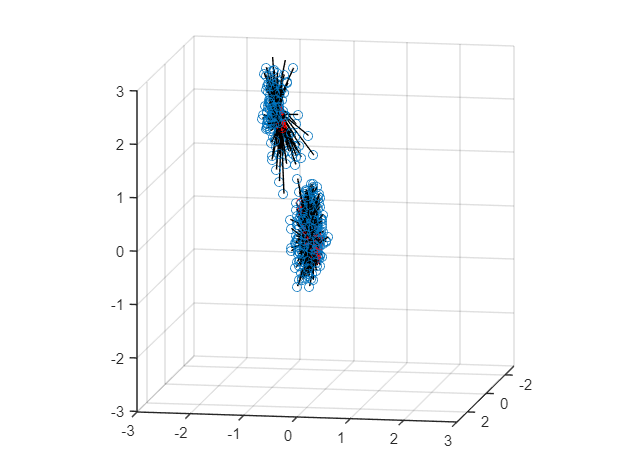

figure
hold on
plot3(cwru_train(:, 1),cwru_train(:, 2),cwru_train(:, 3), 'o');
X1 = [cwru_train(:, 1), Xfit(:, 1), nan*ones(length(cwru_train), 1)];
X2 = [cwru_train(:, 2), Xfit(:, 2), nan*ones(length(cwru_train), 1)];
X3 = [cwru_train(:, 3), Xfit(:, 3), nan*ones(length(cwru_train), 1)];
plot3(X1', X2', X3', '-k', Xfit(:, 1),Xfit(:, 2),Xfit(:, 3), 'or')
grid on
axis([-3 3 -3 3 -3 3]);
axis square
view(100,10);

lossfun = 'mincost';

%SVM
fun = @(XT,yT,Xt,yt)loss(fitcecoc(XT,yT),Xt,yt, 'Lossfun', lossfun);    % svm 이용
h = height(class_train);         % Size of table
cv = cvpartition(h,'KFold',10);

dir = 'forward';
opts = statset('Display','iter');
[inmodel, history] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir, 'nfeatures', num)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 9번 열 추가, 기준값 0.00479725
2단계, 1번 열 추가, 기준값 0.00223331
3단계, 5번 열 추가, 기준값 0.0021104
4단계, 4번 열 추가, 기준값 0.00175028
5단계, 8번 열 추가, 기준값 0.00174542
최종적으로 포함된 열: 1 4 5 8 9 


inmodel = 1×11 logical 배열
   1   0   0   1   1   0   0   1   1   0   0


history = 다음 필드를 포함한 struct :
      In: [5×11 logical]
    Crit: [0.0048 0.0022 0.0021 0.0018 0.0017]


mdl = fitcecoc(cwru_train, class_train);
cvmdl = crossval(mdl);

idx= find(inmodel);  
accuracy_cvmdl = (1 - kfoldLoss(cvmdl))

accuracy_cvmdl = 0.9236

cvmdl_pca = fitcecoc(cwru_train(:,idx),class_train);

cwru_train_select  = cwru_train(:, idx);
cwru_test_select  = cwru_test(:, idx);

mdl_select = fitcecoc(cwru_train_select, class_train);
cvmdl_select = crossval(mdl_select);
accuracy_select = 1 - kfoldLoss(cvmdl_select)

accuracy_select = 0.9190

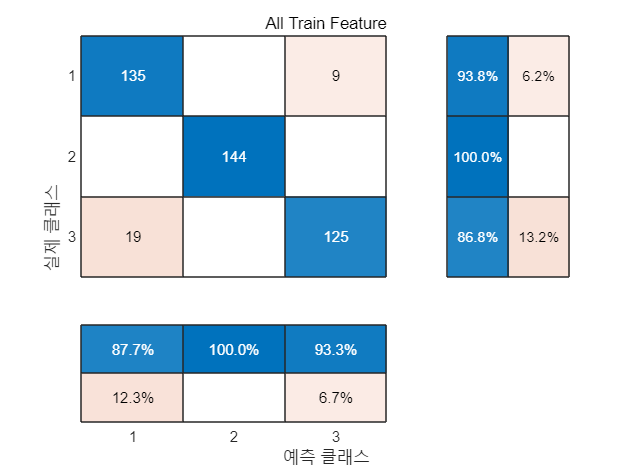

[ntest,ptest] = size(cwru_test);
avg_PCA = repmat(pcaCenter, ntest, 1);
cwru_test_pca = (cwru_test - avg_PCA)/coeff';

%Train
class_pca    = predict(mdl, cwru_train);
class_select = predict(mdl_select, cwru_train(:, idx));
conf_mat_pca = confusionmat(class_train, class_pca);
conf_mat_select = confusionmat(class_train, class_select);

figure; 
confusionchart(conf_mat_pca, ...
    'Title','All Train Feature', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

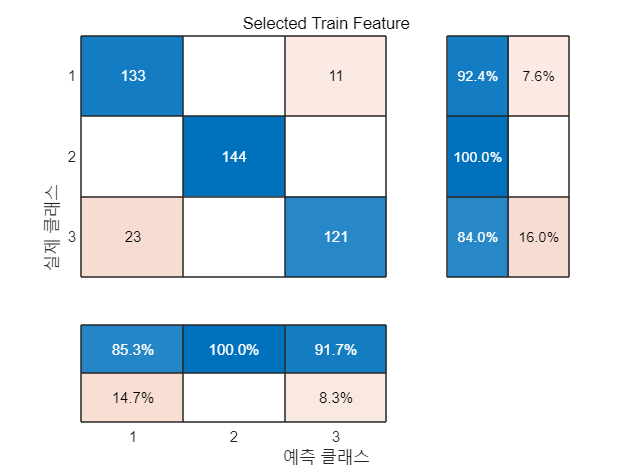

figure;
confusionchart(conf_mat_select, ...
    'Title','Selected Train Feature', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

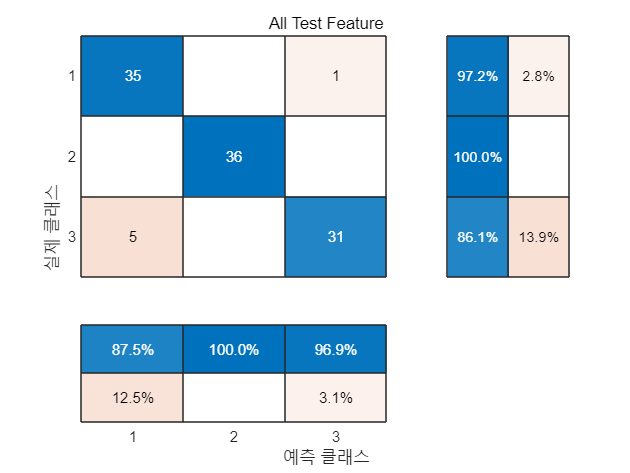

% Test
class_pca    = predict(mdl, cwru_test);
class_select = predict(mdl_select, cwru_test(:, idx));

conf_mat_pca = confusionmat(class_test, class_pca);
figure;
confusionchart(conf_mat_pca, ...
    'Title','All Test Feature', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

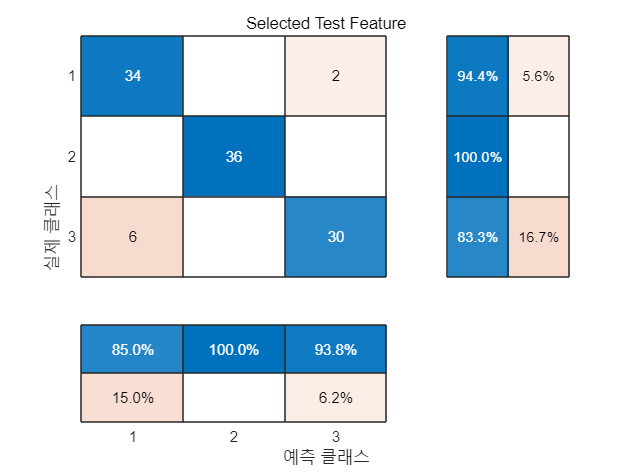

conf_mat_select = confusionmat(class_test, class_select);
figure;
confusionchart(conf_mat_select, ...
    'Title','Selected Test Feature', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

% KNN

fun = @(XT,yT,Xt,yt)loss(fitcknn(XT,yT),Xt,yt, 'Lossfun', lossfun);    % svm 이용
h = height(class_train);         % Size of table
cv = cvpartition(h,'KFold',10);

dir = 'forward';
opts = statset('Display','iter');
[inmodel, history] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir, 'nfeatures', num)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 11번 열 추가, 기준값 0.00312966
2단계, 7번 열 추가, 기준값 0.00193292
3단계, 8번 열 추가, 기준값 0.00171968
4단계, 1번 열 추가, 기준값 0.00172061
5단계, 6번 열 추가, 기준값 0.00125063
최종적으로 포함된 열: 1 6 7 8 11 


inmodel = 1×11 logical 배열
   1   0   0   0   0   1   1   1   0   0   1


history = 다음 필드를 포함한 struct :
      In: [5×11 logical]
    Crit: [0.0031 0.0019 0.0017 0.0017 0.0013]



mdl = fitcknn(cwru_train, class_train);
cvmdl = crossval(mdl);

idx= find(inmodel);  
accuracy_cvmdl = (1 - kfoldLoss(cvmdl))

accuracy_cvmdl = 0.9352

cvmdl_pca = fitcknn(cwru_train(:,idx),class_train);

cwru_train_select  = cwru_train(:, idx);
cwru_test_select  = cwru_test(:, idx);

mdl_select = fitcknn(cwru_train_select, class_train);
cvmdl_select = crossval(mdl_select);
accuracy_select = 1 - kfoldLoss(cvmdl_select)

accuracy_select = 0.9491

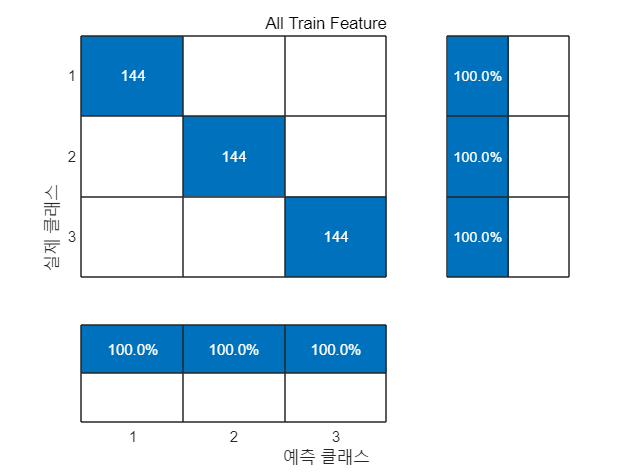


[ntest,ptest] = size(cwru_test);
avg_PCA = repmat(pcaCenter, ntest, 1);
cwru_test_pca = (cwru_test - avg_PCA)/coeff';

%Train
class_pca    = predict(mdl, cwru_train);
class_select = predict(mdl_select, cwru_train(:, idx));
conf_mat_pca = confusionmat(class_train, class_pca);
figure;
confusionchart(conf_mat_pca, ...
    'Title','All Train Feature', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

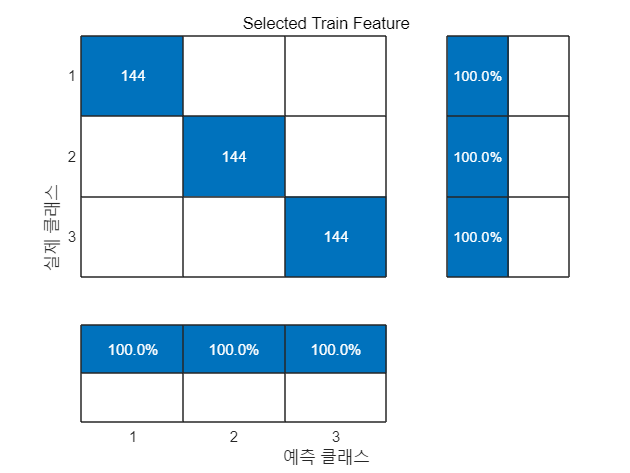

conf_mat_select = confusionmat(class_train, class_select);
figure;
confusionchart(conf_mat_select, ...
    'Title','Selected Train Feature', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

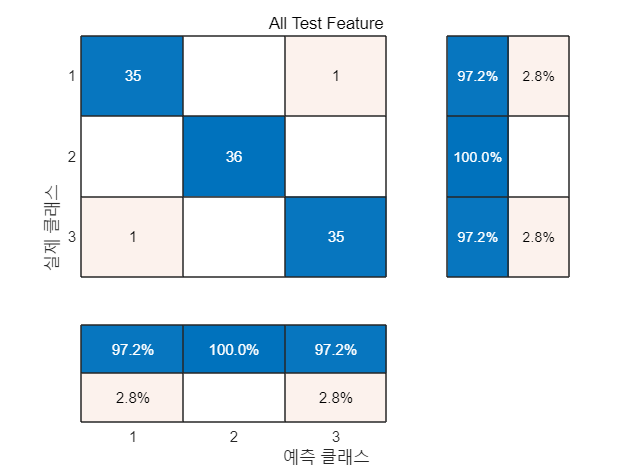



% Test
class_pca    = predict(mdl, cwru_test);
class_select = predict(mdl_select, cwru_test(:, idx));

conf_mat_pca = confusionmat(class_test, class_pca);
figure;
confusionchart(conf_mat_pca, ...
    'Title','All Test Feature', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

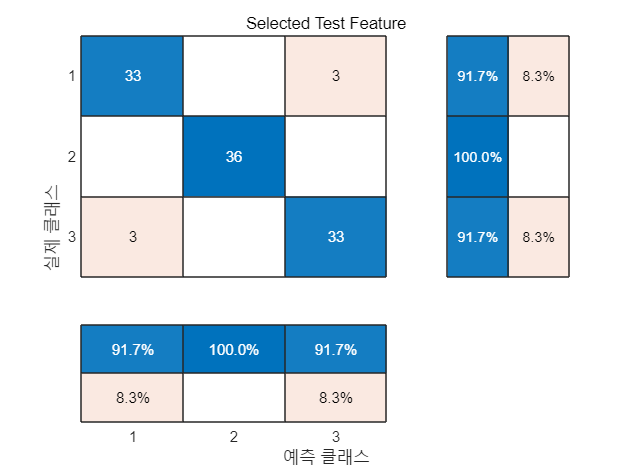

conf_mat_select = confusionmat(class_test, class_select);
figure;
confusionchart(conf_mat_select, ...
    'Title','Selected Test Feature', ...
    'RowSummary','row-normalized', ...
    'ColumnSummary','column-normalized');

## Discussion 

**Classification Method**

In this lab, **KNN** and **SVM** methods are used

- To compare the performance of two classification methods, KNN showed better performance both on recall and precision(over 95%) while SVM showd performance over 90% which is slight lower value. 

- This shows that the dataset given does not have high dimension. KNN shows less accuracy in high dimensional data where SVM shows high accuracy for complex data. 

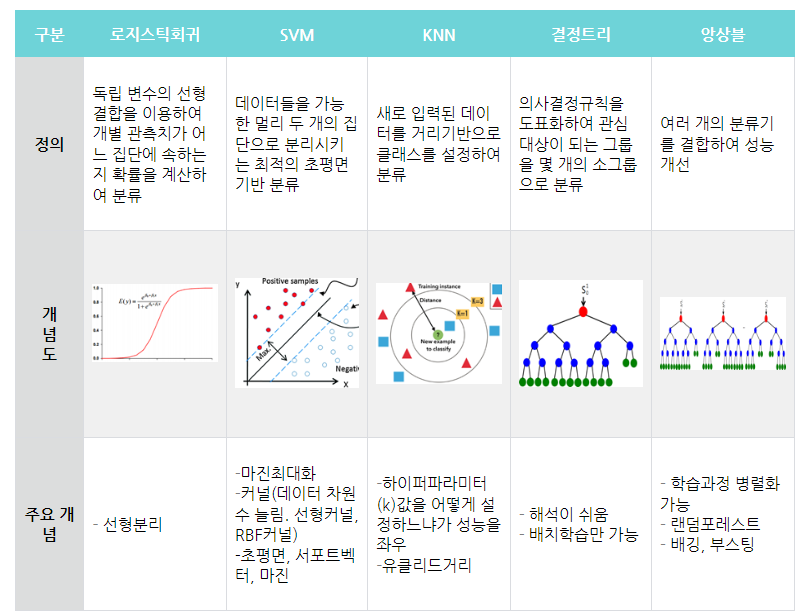

**PCA**

Feature reduction is done in Wrapper Type both forward(adding) and backward(removing). 1, 4, 5, 6, 8, 9 features are finally selected.

After mapping using PCA data, SSE(Squared Sum Error) is 287.02[-]

**Compare Recall and Precision after feature reduction**

- When `feature_idx` is [1:11, 13:42], all the confusion matrix achieved 100% precision and 100% recall, but this may fall into the curse of dimensionality which results in computational burden and overfitting

- Normal data shows 100% on recall and precision for both selected/all features

- **SVM**

- **Train Discussion**

- Precision of inner data dropped from 87.7% to 85.3% while recall dropped from 93.8% to 92.4%

- Outer data's precision dropped from 93.3% to 91.7% and recall dropped from 86.8% to 84.0%

- There are only about 2~3% poor performance on both precision and recall by reducing feature dimension

- 6 out of 11 features are selected using PCA and still maintaining the performance level over 80% for recall and precision

- **Test Discussion**

- Precision of inner data dropped from 87.5% to 85.0% while recall dropped from 97.2% to 94.4%

- Precision of outer data dropped from 96.9% to 93.8% while recall dropped from 86.1% to 83.3%

- Precision of normal data is perfectly classified

- **KNN**

- **Train Discussion**

- Both features(All/Selected) Train data secures 100%

- For this result, overfitting is suspected 

- **Test Discussion**

- Precision of inner data dropped from  97.2% to 91.7% while recall dropped the same.

- Both Recall and Precision of outer data dropped from 97.2% to 91.7%.

- Precision of normal data is perfectly classified

However, PCA is used for **computational efficiency, and prevention of overfitting**.

Accuracy decreased from 94.4% to 92.6% after feature reduction for SVM.

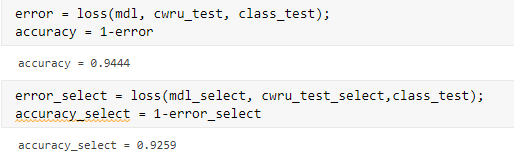

K-fold accuracy also decreased for about 0.002% for SVM.

However, the K-fold accuracy has increased for KNN.

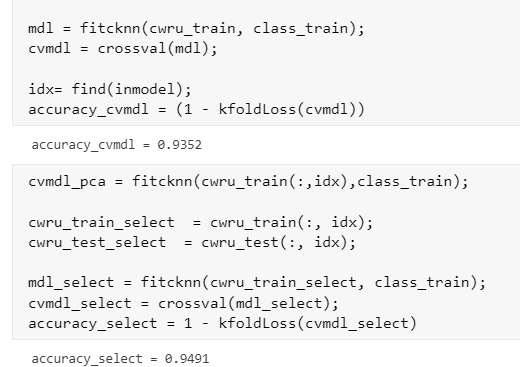

**To do**

- Dimension reduction may be done by t-SNE(t-distributed Stochastic Neighbor Embedding) which can perform better for non-linear data

- Apply Decision Tree or Random Forest models for classification method

- AUC-ROC curve for different feature models and number of selected features should be applied next.

**Conclusion**

KNN is better than SVM for this dataset.

PCA is done to achieve dimension reduction.

90% of accuracy of the model is achieved after dimension reduction.

**Important thing **is that fault data both outer, inner faults are classified as faults and none of normal data is classified as fault, which brings an idea that if this fault data is classified in binary concept, classification is accurate in terms of right or wrong.

**Reference**

**[1] **[**https://bcho.tistory.com/1209**](https://bcho.tistory.com/1209) 

**[2] **[**https://devhwi.tistory.com/20**](https://devhwi.tistory.com/20) 

**[3] **[**https://velog.io/@claude_ssim/%EA%B8%B0%EA%B3%84%ED%95%99%EC%8A%B5-Dimensionality-Reduction-PCA-1**](https://velog.io/@claude_ssim/%EA%B8%B0%EA%B3%84%ED%95%99%EC%8A%B5-Dimensionality-Reduction-PCA-1) 

**[4] **[**https://zhining.tistory.com/87**](https://zhining.tistory.com/87) 

**[5] **[**https://bioinformaticsandme.tistory.com/328**](https://bioinformaticsandme.tistory.com/328) 